The purpose of this project is to implement different interference in FMCW RADAR detection and mitigation algorithms, techniques and methods. 

Weighted Envelop Normalization ( WEN)  and its advanced version ( AWEN) are implemented as two different MATLAB functions, and then tested on a synthetic data 

 This MATLAB project can be only used for rsearch porposes. Please contact me if you have any issue with scripts  or have dificulties to understand some parts of the code

 Developed by Abderrahim BELISSAOUI

 Signal processing & control system engineer 

 Email: abd.belissaoui@gmail.com

**Clear varibales and workspace**

clear all
close all
clc

## RADAR parameters

c=3e8 ;
Bw= 540e6;
R_max=125; %m
Vmax= 60*(1000/3600) ;
d_res=c/(2*Bw) ;

## Chirp parameters

Tc= 45e-6 ; %125m / 45 us
S= Bw/Tc ;

fb_max= 10e6 ; %% 10 MHz
fs= 2.2*10e6  ;

% 2*S*R_max/c ; % R_max=(Fs*c)/(2*S) ;  Sampling frequency f_IF= 2*(S*d)/c   ;
d_res=c/(2*Bw) ;
t= (0:1/fs:Tc-1/fs) ; 

## **CFAR parameters**

refLength=6;
guardLength=1;
offset=4;

## target 1

A1=0.1 ;
R1= 40 ; % target 1 Range
V1=0; % m/s
f_IF1= 2*(S*R1)/c;
S_T1=A1*cos(2*pi*f_IF1*t) ;

## target 2

A2=0.02 ;
R2= 70 ; % target 2 range
V2=0 ; % m/s
f_IF2= 2*(S*R2)/c ;
S_T2=A2*cos(2*pi*f_IF2*t) ;
S_IF_targets= (S_T1+S_T2) ;

## beat signal

S_IF_targets=awgn(S_IF_targets,40) ; % total beat frequency signal
L=length(S_IF_targets) ;

##  Detection Based FFT

Y = fft(S_IF_targets);
B2 = abs(Y/L);
B1 = B2(1:L/2+1);
B1(2:end-1) = 2*B1(2:end-1);
B1=pow2db(B1) ;
f = fs*(0:(L/2))/L;
%
Rng=  (f*c)/(2*S);

## **CFAR detector **

cfarThreshold = CA_CFAR(B1, refLength,guardLength,offset) ;

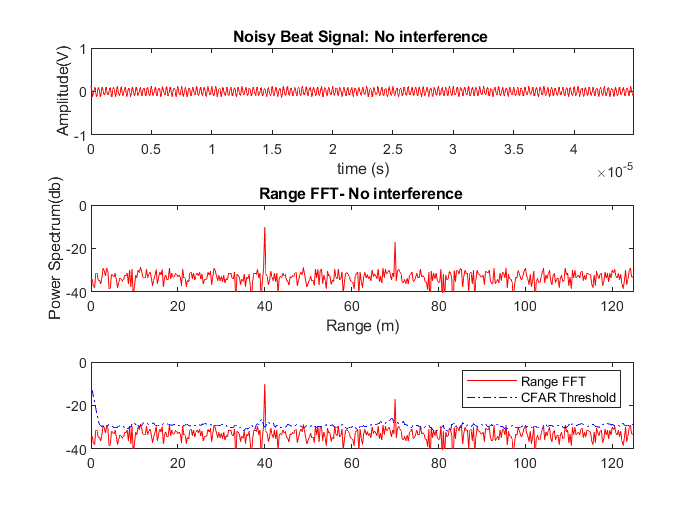

figure
subplot(3,1,1)
plot(t, S_IF_targets,'r')
axis([0 max(t) -1 1])
title('Noisy Beat Signal: No interference ')
xlabel('time (s)')
ylabel('Amplitude(V)')
subplot(3,1,2)
plot(Rng,B1,'r') 
axis([0 R_max -40 0]);
title('Range FFT- No interference ')
xlabel('Range (m)')
ylabel('Power Spectrum(db)')
subplot(3,1,3)
plot(Rng,B1,'r');
axis([0 R_max -40 0]);
hold on,plot(Rng,cfarThreshold,'-.b')
legend('Range FFT','CFAR Threshold')

## adding interference

PL = 0.4*Tc * fb_max;
tS = (0:PL-1)*(1/fb_max);  % Time vector
halfIdx = round(PL/2);
sFreq1=0.4*fb_max ;
sFreq2=0.7*fb_max ;

[S2_P1,phiEnd] = ChirpGenerate(sFreq1, sFreq2, t(1:halfIdx),90);
[S2_P2,phiEnd] = ChirpGenerate(sFreq2, sFreq1, t(1:halfIdx),phiEnd);
S2_P3= zeros(1,L-PL) ;
S2 = [S2_P3,S2_P1, S2_P2];
S2 = 0.2*S2 ;

## Tolal signal

    S_IF= (S_T1+S_T2)+S2 ;
    S_IF=awgn(S_IF,40);
    % figure 
    % snr(S_IF)
    % title("snr of total beat signal")

## Detection based FFT

    Y = fft(S_IF);
    Q2 = abs(Y/L);
    Q1 = Q2(1:L/2+1);
    Q1(2:end-1) = 2*Q1(2:end-1);
    Q1=pow2db(Q1) ;
    f = fs*(0:(L/2))/L;
    Rng= (f*c)/(2*S);
    %


## **CFAR detector**

cfarThreshold = CA_CFAR(Q1, refLength,guardLength,offset) ;

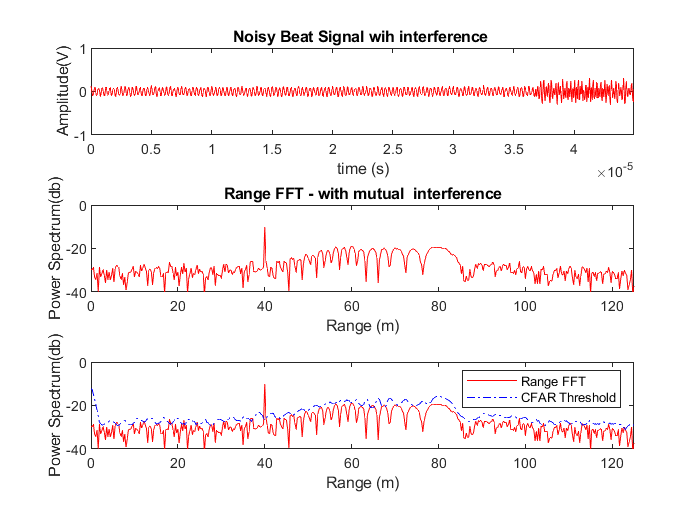

    figure
    subplot(3,1,1)
    plot(t, S_IF,'r') ;
    axis([0 max(t) -1 1])
    title('Noisy Beat Signal wih interference ')
    xlabel('time (s)')
    ylabel('Amplitude(V)')
    subplot(3,1,2)
    plot(Rng,Q1,'r') 
    axis([0 R_max -40 0]);
    title('Range FFT - with mutual  interference')
    xlabel('Range (m)')
    ylabel('Power Spectrum(db)')
    subplot(3,1,3)
    plot(Rng,Q1,'r');
    axis([0 R_max -40 0]);
    hold on,plot(Rng,cfarThreshold,'-.b')
    legend('Range FFT','CFAR Threshold') 
    xlabel('Range (m)')
    ylabel('Power Spectrum(db)')

## WEN

        [mlmax_F,mlmax_B,r,m_new] = WEN(S_IF,80) ;

## Detection based FFT

        Y = fft(m_new);
        P2 = abs(Y/L);
        P1 = P2(1:L/2+1);
        P1(2:end-1) = 2*P1(2:end-1);
        P1=pow2db(P1) ;
        f = fs*(0:(L/2))/L;
        Rng= (f*c)/(2*S);
        %

cfarThreshold = CA_CFAR(P1, refLength,guardLength,offset) ;

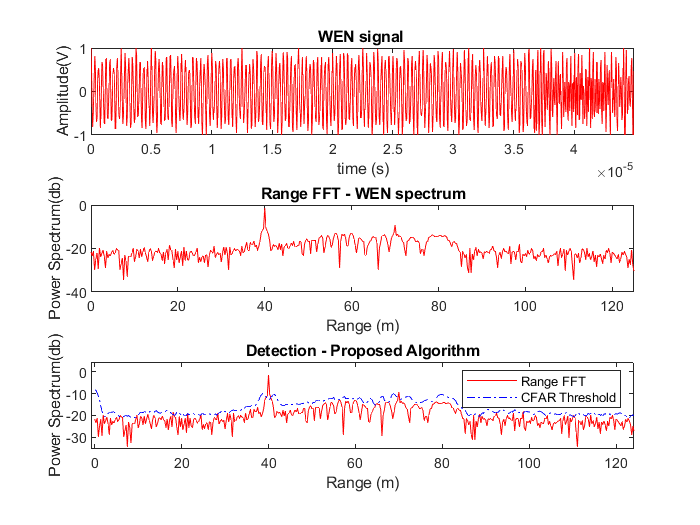

figure      
subplot(3,1,1)
plot(t, m_new,'r') ;
axis([0 max(t) -1 1])
title('WEN signal ')
xlabel('time (s)')
ylabel('Amplitude(V)')
subplot(3,1,2)
plot(Rng,P1,'r') 
axis([0 R_max -40 0]);
title('Range FFT - WEN spectrum')
xlabel('Range (m)')
ylabel('Power Spectrum(db)')
subplot(3,1,3)
plot(Rng,P1,'r');
axis([0 R_max -40 0]);
title('Detection - Proposed Algorithm')
hold on,plot(Rng,cfarThreshold,'-.b') ; 
legend('Range FFT','CFAR Threshold')
  xlabel('Range (m)')
  ylabel('Power Spectrum(db)')